# Загрузка, обработка и визуализация экспериментальных данных

**Самостоятельная работа**

Обработайте данные по среднесуточной температуре в Москве за 2017 год.

## Чтение данных

Считайте данные из файла `tempdata.csv` в переменную `T` типа `table`

T = readtable('tempdata.csv')

T = 365×4 table
       DATE        TMIN     TMAX     TAVG 
    ___________    _____    _____    _____

    01-Jan-2017      NaN      NaN      NaN
    02-Jan-2017      NaN      NaN      0.7
    03-Jan-2017      NaN      NaN     -6.7
    04-Jan-2017    -11.7      NaN    -10.1
    05-Jan-2017      NaN      NaN      -13
    06-Jan-2017      NaN      NaN    -25.6
    07-Jan-2017    -29.9    -23.5    -27.3
    08-Jan-2017    -28.6    -21.5    -25.2
    09-Jan-2017    -25.5      NaN    -19.9
    10-Jan-2017    -16.1     -6.7     -9.1
    11-Jan-2017      NaN      NaN     -9.7
    12-Jan-2017      -11      NaN     -8.3
    13-Jan-2017       -7       -3     -3.8
    14-Jan-2017     -5.1       -1     -2.6
    15-Jan-2017     -1.9     -0.5     -1.1
    16-Jan-2017      NaN      0.4     -1.3


Постройте график среднесуточной температуры (столбец `TAVG`) в зависимости от даты измерения

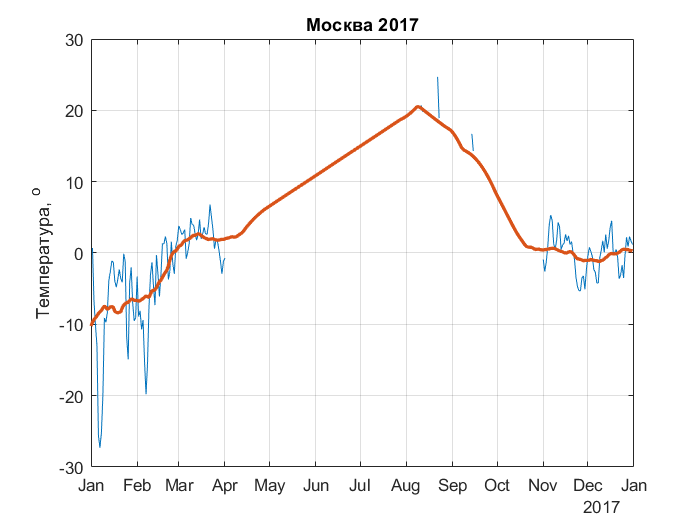

plot(T.DATE, T.TAVG)

## Статистический анализ

В пеменную `Tmin` запишите минимальную среднесуточную температуру (минимальное значение `TAVG`), а в переменную `Tmax` - максимальную

Tmin = min(T.TAVG)

Tmin = -27.3000

Tmax = max(T.TAVG)

Tmax = 24.7000

На основании полученных данных посчитайте диапазон изменения (разброс) среднесуточной температуры. Результат запишите в переменную `Trange`

Trange = Tmax - Tmin

Trange = 52

На графике видно, что данные содержат много пропусков. В переменную `N` запишите количество пропущенных значений в столбце `TAVG`

N = nnz(ismissing(T.TAVG))

N = 204

## Обработка данных

Заполните пропуски в таблице T методом линейной интерполяции

T = fillmissing(T, 'linear')

T = 365×4 table
       DATE         TMIN       TMAX      TAVG 
    ___________    _______    _______    _____

    01-Jan-2017        6.5      -35.5      8.1
    02-Jan-2017    0.43333      -33.5      0.7
    03-Jan-2017    -5.6333      -31.5     -6.7
    04-Jan-2017      -11.7      -29.5    -10.1
    05-Jan-2017    -17.767      -27.5      -13
    06-Jan-2017    -23.833      -25.5    -25.6
    07-Jan-2017      -29.9      -23.5    -27.3
    08-Jan-2017      -28.6      -21.5    -25.2
    09-Jan-2017      -25.5      -14.1    -19.9
    10-Jan-2017      -16.1       -6.7     -9.1
    11-Jan-2017     -13.55    -5.4667     -9.7
    12-Jan-2017        -11    -4.2333     -8.3
    13-Jan-2017         -7         -3     -3.8
    14-Jan-2017       -5.1         -1     -2.6
    15-Jan-2017       -1.9       -0.5     -1.1
    16-Jan-2017         -5        0.4     -1.3


Выделите общий характер изменения среднесуточной температуры в Москве за 2017 год. Для этого сгладьте данные в столбце `TAVG` методом скользящего среднего по 30 точкам (дням). Результат запишите в новый столбец `TAVG2`

T.TAVG2 = movmean(T.TAVG, 30)

T = 365×5 table
       DATE         TMIN       TMAX      TAVG      TAVG2 
    ___________    _______    _______    _____    _______

    01-Jan-2017        6.5      -35.5      8.1     -10.24
    02-Jan-2017    0.43333      -33.5      0.7    -9.6813
    03-Jan-2017    -5.6333      -31.5     -6.7    -9.3412
    04-Jan-2017      -11.7      -29.5    -10.1    -9.0889
    05-Jan-2017    -17.767      -27.5      -13    -8.8053
    06-Jan-2017    -23.833      -25.5    -25.6      -8.48
    07-Jan-2017      -29.9      -23.5    -27.3    -8.2476
    08-Jan-2017      -28.6      -21.5    -25.2    -8.0591
    09-Jan-2017      -25.5      -14.1    -19.9     -7.713
    10-Jan-2017      -16.1       -6.7     -9.1    -7.4417
    11-Jan-2017     -13.55    -5.4667     -9.7      -7.62
    12-Jan-2017        -11    -4.2333     -8.3       -7.9
 

## Визуализация данных

На уже построенный график `TAVG` от `DATE` добавьте график столбца `TAVG2 (его линий должна иметь толщину`` 2``)`

hold on
plot(T.DATE, T.TAVG2, 'LineWidth', 2)
hold off

Включите сетку

grid on

Подпишите заголовок графика: **Москва 2017**

title('Москва 2017')

Подпишите ось ординат: **Температура, ^o**

ylabel('Температура, ^o')